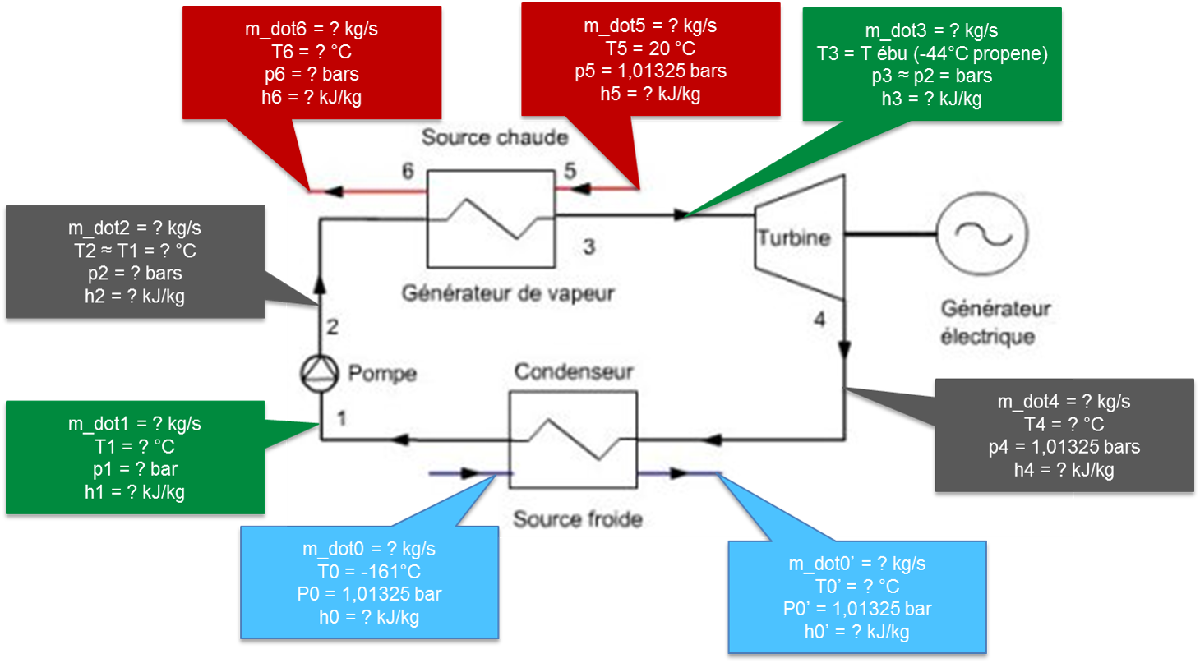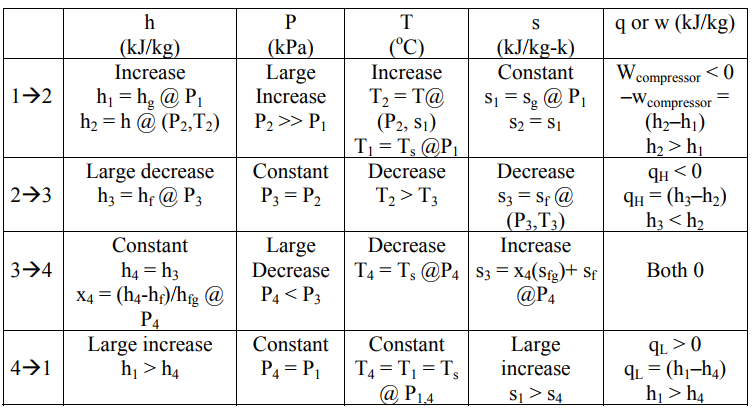

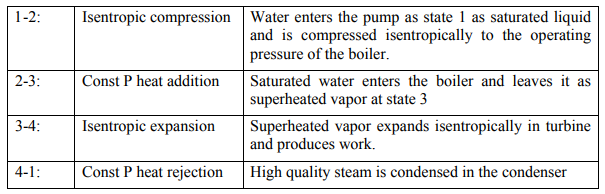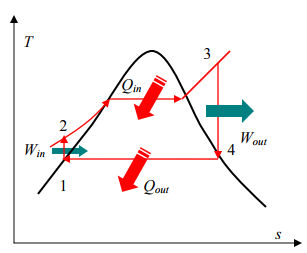

**Fluids**: ethane, R41, R125, R143a, R32, propylen, propane, R134q

P   Pressure [kPa]

H   Enthalpy [J/kg]

S   Entropy [J/(kg K)]

T   Temperature [K]

x   Quality (vapor fraction) (kg/kg)

**Assumptions: **Pump and turbine are adiabatic and reversible (sentropic) compression and expansion, respectively.

**Inputs:**

% Environment
T_ambient = 15; % Temperature of environment [°C]
T_mini = -20; % Minimum operational temperature [°C]

% Working fluid
fluids = ["propane","ethane","R41","R125","R143a","R134a","R32","propylene","propane","carbon dioxide","water"];
fluid = 'propane';
T_solidification_fluid = 0; % Temperature of fusion of working fluid [°C]
%T_boiling_fluid = convtemp(refpropm('T','P',101.325,'Q',0,'WATER'),'K','C'); % Temperature of boiling at 1 atm [°C]

% Turbine inlet
T3 = 100; % Temperature at turbine inlet [°C]
P3 = 3; % Pressure at turbine inlet [bars}

% Condenser inlet
P4 = 1.1; % Pressure at turbine outlet [bars]

**Unit convertions:**

T3 = convtemp(T3,'C','K'); % Temperature at turbine inlet [K]
P3 = P3*100; % Condenser pressure [kPa]
P4 = P4*100; % Boiler pressure [kPa]

**Thermodynamic Rankine cycle:**

***    - Turbine inlet:***

h3 = refpropm('H','T',T3,'P',P4,fluid);
s3 = refpropm('S','P',P4,'H',h3,fluid); 

***    - Condenser inlet:***

 s4=s3; % entropy remains the same through turbine (ideal)
 h4 = refpropm('H','P',P3,'S',s4,fluid);
 steam_quality_x4 = refpropm('Q','P',P3,'S',s4,fluid);

***    - Pump inlet:***

T1 = refpropm('T','P',P3,'Q',0,fluid); % Saturation temperature

Undefined function or variable 'P1'.

h1 = refpropm('H','P',P3,'Q',0,fluid); % Saturated liquid enthalpy
v1 = refpropm('H','P',P3,'Q',1,fluid); % Saturated vapour enthalpy

***    - Evaporator inlet:***

h2 = h1 + v1*(P4-P3)*1e2; % calculating h4 from pump work


**Constraints**:

% The solidification temperature of the working fluid shall be 20 % higher than the ambient temperature
% assert(T_solidification_fluid >= 1.2*T_ambient)

% Le titre de vapeur de détente ne doit pas être trop faible faute de quoi il se forme des goutelletes de liquide trop grosses qui constituent un abrasif dangeureux pour la tenue mécanique des aubages
% assert(0.7 < steam_quality_x4 < 0.85, 'vapor quality not good', )

% The pressure of condensation / evaporation shall be greater than 1 bar to prevent air infiltration ithin the system

% Environmental constraints: comply with standards, Ozone Depletion Potential (ODP) = 0, Global Warming Potential as low as possible

% Safety constraints : non-toxic, non-inflammable

Wp = h2 - h1 % Pump work
Qin = h3 - h2 % Evaporator heat input
Wt = h3 - h4 % Turbine work
Qout = h4 - h1 % Condenser heat out

Wnet = Wt + Wp % Cycle net specific work

eff = (Wt - Wp)/Qin % Efficiency